# Experiment with LSTMpathToEEG model(3 channels)

## Load data

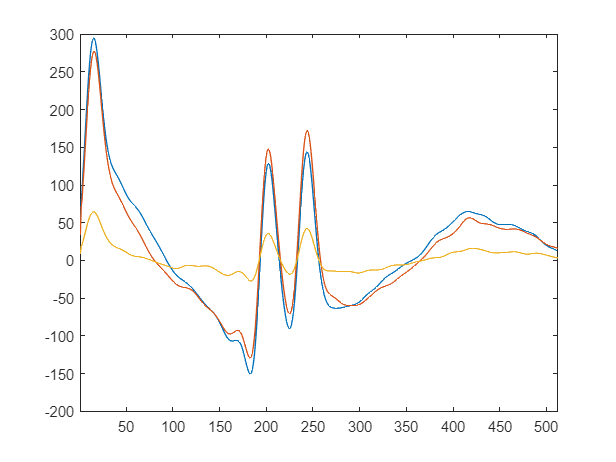

XTrain = load(fullfile('DataSet','HyperparameterSearch','Train','XSearchTrain.mat')).XSearchTrain;
YTrain = load(fullfile('DataSet','HyperparameterSearch','Train','YSearchTrain.mat')).YSearchTrain;

XTest = load(fullfile('DataSet','HyperparameterSearch','Test','XSearchTest.mat')).XSearchTest;
YTest = load(fullfile('DataSet','HyperparameterSearch','Test','YSearchTest.mat')).YSearchTest;

trainDs = {XTrain, YTrain};
testDs = {XTest, YTest};

figure;i = 1;
plot(XTrain{i}');
xlim([1 size(XTrain{i},2)]);

## Hyper-parameter search

|===================================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | miniBatchSize| learningrate |    numBlocks | numHiddenUni-|
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |              | ts           |
|===================================================================================================================================|
|    1 | Best   |     0.12247 |      258.12 |     0.12247 |     0.12247 |          111 |     0.091956 |            5 |           47 |
|    2 | Accept |     0.12247 |      1509.6 |     0.12247 |     0.12247 |           28 |     0.051448 |            5 |          222 |
|    3 | Best   |    0.073255 |      150.83 |    0.073255 |    0.073255 |           52 |    0.0010905 |            1 |           82 |
|    4 | Accept |    0.082341 |      1229.8 |    0.073255 |   

|   37 | Accept |           1 |      4.4173 |    0.070734 |    0.070734 |           94 |     0.091444 |            1 |          107 |
|   38 | Accept |     0.12247 |      337.05 |    0.070734 |    0.070734 |          128 |     0.073739 |            8 |           23 |
|   39 | Accept |    0.072505 |      141.88 |    0.070734 |    0.070734 |          108 |     0.014594 |            2 |            9 |
|   40 | Accept |    0.073693 |      354.69 |    0.070734 |    0.070734 |          122 |     0.014118 |            2 |          213 |
|===================================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | miniBatchSize| learningrate |    numBlocks | numHiddenUni-|
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |              | ts           |
|=============================================================

|   47 | Accept |    0.071673 |      3661.6 |    0.070734 |    0.070734 |          128 |    0.0052247 |            8 |          233 |
|   48 | Accept |    0.078813 |      261.93 |    0.070734 |    0.070734 |          122 |    0.0002252 |            5 |           15 |
|   49 | Accept |    0.074046 |       91.01 |    0.070734 |    0.070734 |          126 |     0.012783 |            1 |           29 |
|   50 | Accept |     0.12865 |      242.63 |    0.070734 |    0.070734 |          114 |   0.00040726 |            3 |            1 |
|   51 | Accept |    0.083604 |      266.58 |    0.070734 |    0.070734 |          126 |   0.00010792 |            6 |           15 |
|   52 | Accept |    0.073263 |      431.72 |    0.070734 |    0.070734 |           96 |    0.0051901 |            8 |            3 |
|   53 | Accept |    0.085046 |      276.95 |    0.070734 |    0.070734 |          125 |    0.0022767 |            6 |           27 |
|   54 | Accept |     0.12247 |      332.36 |    0.070734 |   

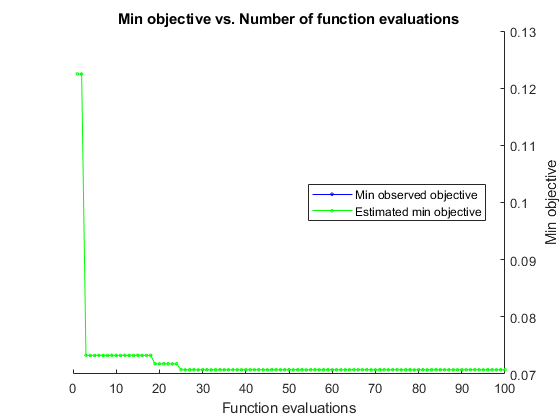


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 100 reached.
Total function evaluations: 100
Total elapsed time: 46605.9492 seconds
Total objective function evaluation time: 46542.421

Best observed feasible point:
    miniBatchSize    learningrate    numBlocks    numHiddenUnits
    _____________    ____________    _________    ______________

         66           0.0031616          1             111      

Observed objective function value = 0.070734
Estimated objective function value = 0.070734
Function evaluation time = 161.5658

Best estimated feasible point (according to models):
    miniBatchSize    learningrate    numBlocks    numHiddenUnits
    _____________    ____________    

maxEpochs = 30;
optimVars = [
    %miniBatchSize,learningrate,numBlocks,numHiddenUnits;
    optimizableVariable('miniBatchSize',[8 128],'Type','integer')%[8 128]
    optimizableVariable('learningrate',[1e-4 1e-1],'Type','real',"Transform","log")
    optimizableVariable('numBlocks',[1 8],'Type','integer')%[1 5]
    optimizableVariable('numHiddenUnits',[1 256],'Type','integer')];


objectFunction = objectFunctionLSTM(trainDs, testDs,  maxEpochs);
    
% optimizer
BayesObject = bayesopt( objectFunction,             optimVars, ...
                        'MaxTime',                  24*60*60, ...
                        'Verbose',                  1,...
                        "UseParallel",              false,...
                        'IsObjectiveDeterministic', true, ...
                        'ParallelMethod',           "clipped-model-prediction",...
                        'MaxObjectiveEvaluations',  100,...
                        'ExplorationRatio',         0.6,...
                        'AcquisitionFunctionName', 'expected-improvement-per-second-plus');

optVars = bestPoint(BayesObject);

save("HyperparameterSearch\OptVars\LSTMBayesObject.mat","BayesObject","-mat");

Error using save
Must be a text scalar.

save("HyperparameterSearch\OptVars\LSTMoptVars.mat","optVars","-mat");


    % Evaluate and train the network with the optimal parameters
[valError,~,net, YPred, YTest] = BayesObject.ObjectiveFcn(optVars,1);

TX = {};
for k = 1:numel(testDs)
    TX{end+1} = testDs{k}{1};
end


TY = [];
Y = [];
YTest = YTest.';
for k = 1:numel(testDs{1})
    TY = [TY;YTest{k}];
    Y = [Y;YPred{k}];
end

confusionchart(TY(:),Y(:),'Normalization','column-normalized');